# **Setup a Nonlinear Performance Simulation**

Note: Setup the dependencies by running the script: **setup_prerequisites.m**

We are going to use units of measurements consistently throughout the code and we need to convert back and forth from SI units to English units.

Clear all first

clear all; close all; clc;

## **Lockeed C-130 Aircraft - configuration constants**

Wing reference surface, $S_{\;\mathrm{W}}$

wingSurface = 3010 * str2u('ft^2');

Wing span, $b$

wingSpan    = 146 * str2u('ft');

Wing aspect ratio, $AR_{\;\mathrm{W}}$

aspectRatio = wingSpan^2/wingSurface;

Drag polar Oswald factor, $e_{\;\mathrm{Oswald}}$

oswald      = 0.95;


Effective aspect ratio,$AR_{\;\mathrm{e}} = AR_{\;\mathrm{W}} \, e_{\;\mathrm{Oswald}}$

aspectRatioE = aspectRatio*oswald;

Constant,$\pi AR_{\;\mathrm{e}} = \pi AR_{\;\mathrm{W}} \, e_{\;\mathrm{Oswald}}$

piARe       = pi*aspectRatioE;

Parassite drag coefficient,$C_{\;D0}$

cD0         = 0.02;

Weights, $W_{\;\mathrm{max}}\,, W_{\;\mathrm{empty}}\,, W_{\;\mathrm{max,f}}$

weightMax       = 327000 * str2u('lbf');
weightEmpty     = 157000 * str2u('lbf');
weightMaxFuel   = 170000 * str2u('lbf');

Nominal weight, $W_{\;\mathrm{nom}} = W_{\;\mathrm{empty}}+ 0.75 \,W_{\;\mathrm{max,f}}$

weightNom = weightEmpty + 0.75*weightMaxFuel;

Fuel flow rate constant, $\dot{m} = K_{\;\dot{W}} \, T$

kWdot       = 4e-6 * str2u('slug/(lbf*s)');

Minimum/Maximum speed $V_{\;\mathrm{min}}$, $V_{\;\mathrm{max}}$, maximum thrust $T_{\;\mathrm{max}}$, maximum bank angle $\nu_{\;\mathrm{max}}$

speedMin       = 200 * str2u('mph');
speedMax       = 600 * str2u('mph');
thrustMax      = 72000 * str2u('lbf');
bankAngleMax   = 30 * str2u('deg');

## Initial conditions

altitude $h_{\;0} = h(0)$, air density $\rho_0 = \rho\left(h_0\left)$

altitude_0   = 20000 * str2u('ft');
[temp_0, a_0, p_0, rho_0] = atmosisa(altitude_0/u.m);
airDensity_0 = rho_0 * str2u('kg/m^3');

Drag polar coefficients

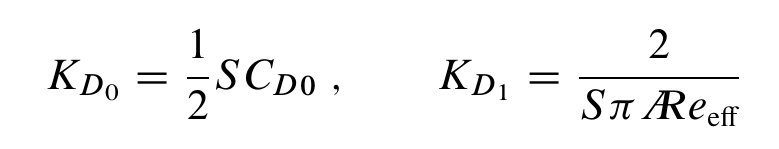

kD0   = 0.5*cD0*wingSurface;
kD1   = 2/(piARe*wingSurface);

Lift curve slope $C_{\;L\,\alpha}$ and zero-lift angle of attack $\alpha_{\;0L}$

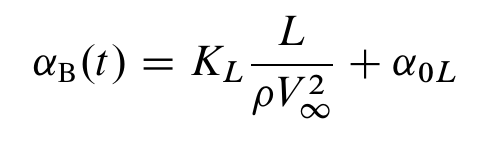

cLalpha = 0.1 / str2u('deg');
alpha0L = -2.86 * str2u('deg');

Lift factor

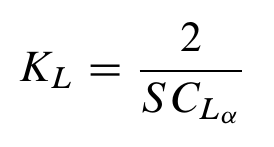

kL = 2.0/(wingSurface * cLalpha);

Limitation on angle of attack

alphaBody_max = 8 * str2u('deg');
limitLMaxOverRhoV2 = (alphaBody_max - alpha0L)/kL;

## Initial winds

wind_0 = [25, 25, 0] * str2u('mph');

## Initial states and controls

weight_0          = weightNom;
mass_0            = weight_0 / (9.81 * str2u('m/s^2'));
speed_0           = 400 * str2u('mph');
flightPathAngle_0 = 0 * str2u('deg');
headingAngle_0    = 0 * str2u('deg');
xE_0              = 0 * str2u('m');
yE_0              = 0 * str2u('m');
altitude_0        = 10000 * str2u('ft');
bankAngle_0       = 0 * str2u('deg');

Initial lift, $L_{\;0} = W_0 \cos\gamma_0$

lift_0            = weight_0*cos(flightPathAngle_0)/cos(bankAngle_0);

Initial drag

 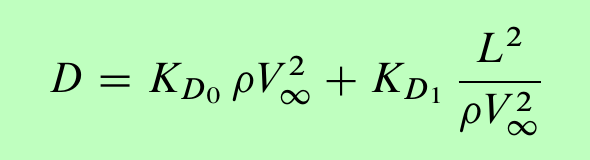

drag_0            = kD0 * airDensity_0 * speed_0^2 ...
                    + kD1 * (lift_0^2)/(airDensity_0 * speed_0^2);
                

Initial thrust, $T_0 = D_0 + W_0 \sin\gamma_0$

thrust_0          = drag_0 + weight_0*sin(flightPathAngle_0);

## Control Lag Time Constants

     

pT  = 2.0 * str2u('rad/s');
pL  = 2.5 * str2u('rad/s');
pNu = 1.0 * str2u('rad/s');

## Guidance law gains

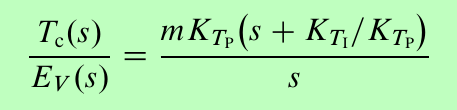   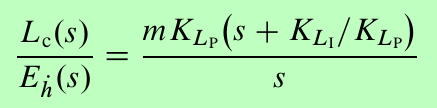  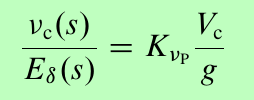

kTI = 0.002 / str2u('s^2');
kTP = 0.080 / str2u('s');
kLI = 0.010 / str2u('s^2');
kLP = 0.500 / str2u('s');
kNu = 0.075 / str2u('s');

## Commanded values (Initial)

Speed, rate of climb, heading

speed_c1           = 450 * str2u('mph');
speed_c2           = 420 * str2u('mph');
speed_c3           = 400 * str2u('mph');
speed_c4           = 400 * str2u('mph');

flightPathAngle_c1 = 5 * str2u('deg');
flightPathAngle_c2 = 0 * str2u('deg');
flightPathAngle_c3 = -5 * str2u('deg');
flightPathAngle_c4 = 0 * str2u('deg');

hDot_c1            = speed_c1* sin(flightPathAngle_c1);
hDot_c2            = speed_c2 * sin(flightPathAngle_c2);
hDot_c3            = speed_c3 * sin(flightPathAngle_c3);
hDot_c4            = speed_c4 * sin(flightPathAngle_c4);

headingAngle_c1    = 15 * str2u('deg');
headingAngle_c2    = 15 * str2u('deg');
headingAngle_c3    = 0 * str2u('deg');
headingAngle_c4    = 0 * str2u('deg');